# Finding a 2D SSM for a von Kármán beam

This is an example of how to reconstruct a slow 2D SSM of a 6-degree of freedom mechanical system using synthetic measurements of the full state space. In this example, we consider a von Kármán beam with nonlinear damping, discretized with 2 elements.

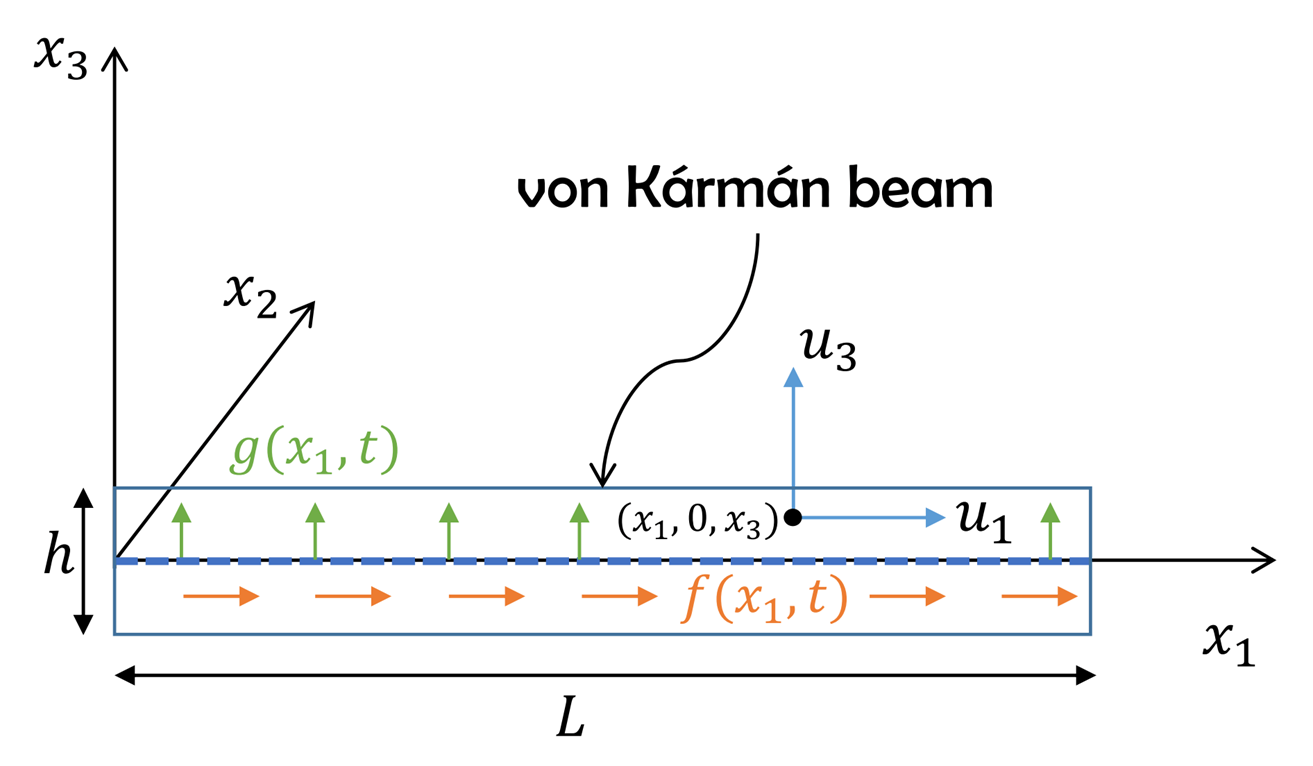

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) = \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $N\times N$ mass, stiffness, and damping matrices, respectively.

Using SSMTool 2.0 [1], we rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0} 
& \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c} \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

[1]  [https://github.com/haller-group/SSMTool-2.0/releases](https://github.com/haller-group/SSMTool-2.0/releases) 

nElements = 2;
E       = 70e9;   % Young's modulus
rho     = 2700;   % density
nu      = 0.3;    % nu
kappa   = 3e7;    % material linear damping modulus
l       = 1;      % beam length
h       = 20e-3;  % height
b       = 50e-3;  % width

[M,C,K,fnl] = von_karman_model(nElements, E, rho, nu, kappa, l, h, b);

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:00


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)
DS = DynamicalSystem();
set(DS, 'M', M, 'C', C, 'K', K, 'fnl', fnl);
F = @(t,x) DS.odefun(t,x);

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation. In this case we will use one trajectory as the training set and another one as the test set.

nTraj = 2;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);

We now set the initial conditions for the trajectories. Our training trajectory is initialized by applying a point load at the beam tip, which is removed at the start of the simulation. For the test set trajectory, we instead apply a torque. We expect the trajectories to eventually converge onto a slow 2D manifold, which will be identified and used to reduce the system dynamics.

loadvector = zeros(n,nTraj);
loadvector(n,1) = 80;    % point load, [N]
loadvector(n-1,2) = 100; % torque, [Nm]
w0 = -K\loadvector(:,1); % linear initial guess
for iLoad = 1:nTraj
    f_eq = @(w)([zeros(n) M]*F(0,[w; zeros(n,1)]) + loadvector(:,iLoad));
    w0 = fsolve(f_eq, w0);
    IC(:,iLoad) = [w0; zeros(n,1)];
end


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>

Equation solved, solver stalled.

fsolve stopped because the relative 

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the full state space, so the `observable` function is the identity.

observable = @(x) x;
tEnd = 2;
nSamp = 3000;
dt = tEnd/(nSamp-1);
xData = integrateTrajectories(F, observable, tEnd, nSamp, nTraj, IC);

simulating trajectory 1 of 2...
simulating trajectory 2 of 2...


## Data filtering

We need to make sure that the data that we use to identify the slow manifold lies close to it. We can do this by plotting a spectrogram of the beam tip displacement. In general, there may be many vibratory modes present at first, but the faster ones quickly die out. 

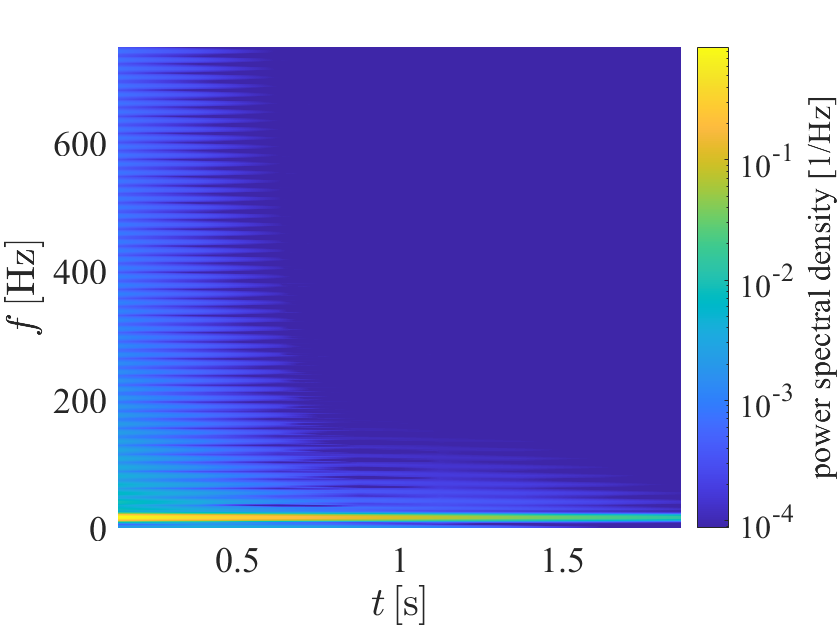

SSMDim = 2;
showSpectrogram(xData(indTrain,:), 5);

Next, we use the information from the spectrogram to remove the first part of the training data. After the first few oscillations have passed, there is one dominant mode left in the frequency spectrum. We keep only the data in the time interval `sliceInt`.

sliceInt = [0.1, tEnd];
xDataTrunc = sliceTrajectories(xData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

The eigenspace $V_e$ of the two slowest modes is unknown in this case. Trajectories are assumed to lie close to an invariant manifold that is tangent to this eigenspace, as shown in the figure below.

 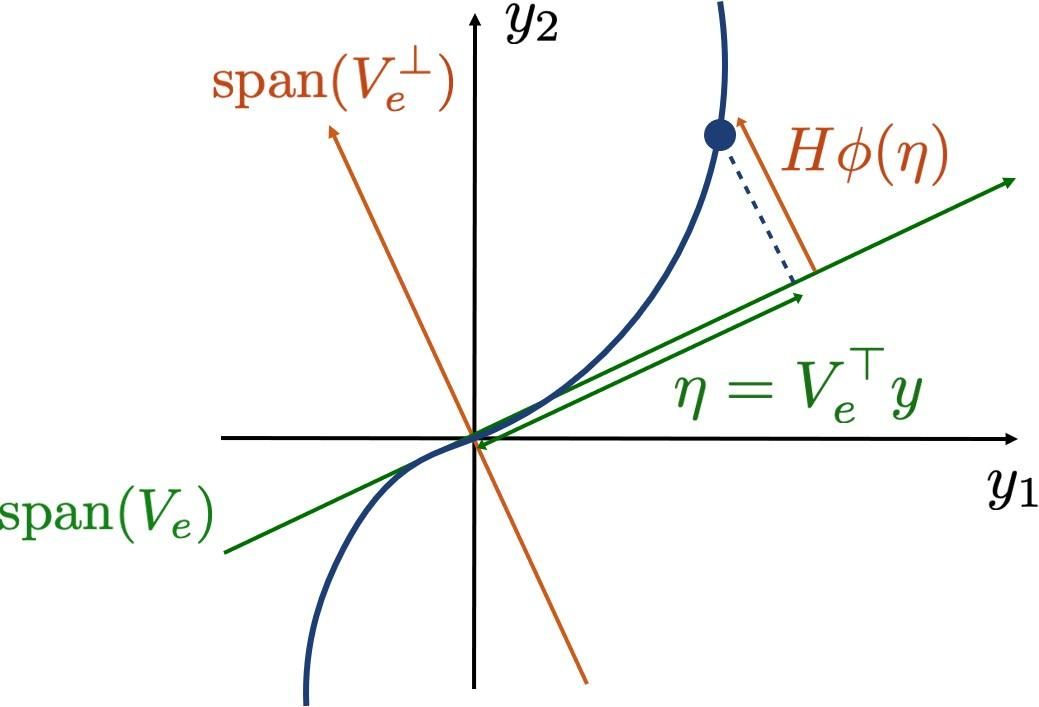

We therefore seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimising a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMparametrization`.

SSMOrder = 3;
[V, SSMFunction, mfdInfo] = IMparametrization(xDataTrunc(indTrain,:), SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.112379e-08    1.776e-14    2.960e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the plane. 

yData = getProjectedTrajs(xData, V);
yDataTrunc = getProjectedTrajs(xDataTrunc, V);

We plot the test and training set trajectories projected onto the plane. After all initial transients die out, the trajectories seem to be confined to a slowly decaying oscillating eigenmode.

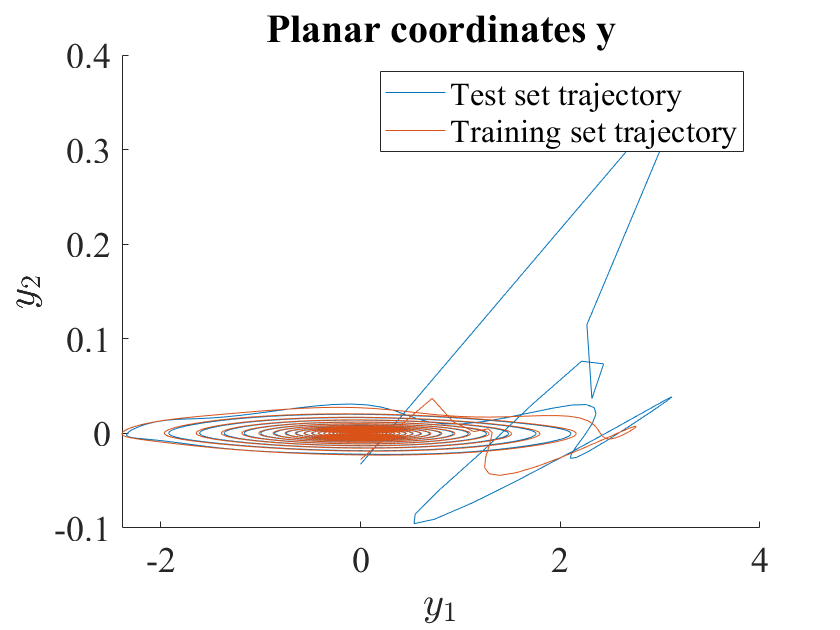

plotReducedCoords(yData);
legend({'Test set trajectory', 'Training set trajectory'})

Furthermore, we draw the end tip component of the manifold shape along with the trajectory from the training set. The trajectories converge onto the slow manifold after vibrations in the modes of larger damping die out.

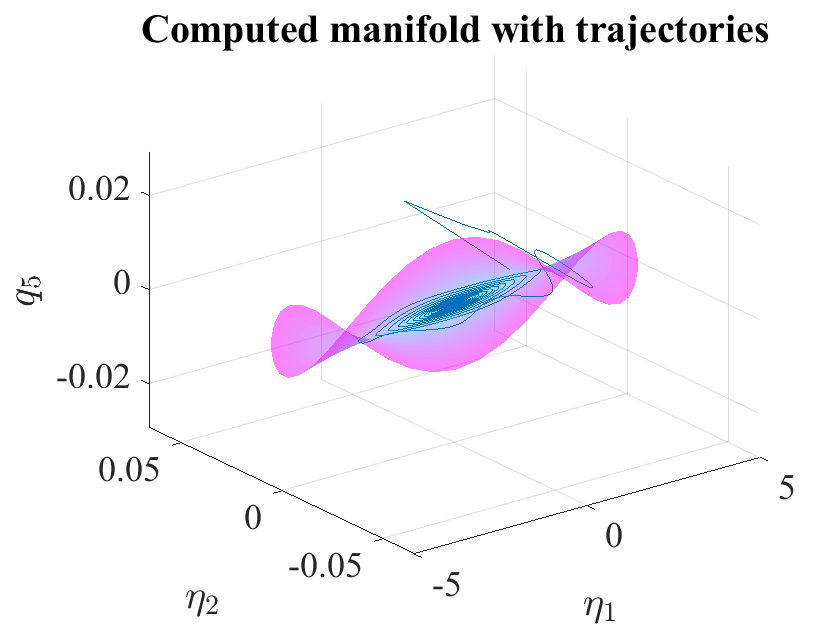

plotSSMWithTrajectories(xData(indTrain,:), SSMFunction, n-1, V, 50, 'SSMDimension', SSMDim)

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMdynamics_map` fits a polynomial map


$$y_{k+1} = W_r \phi(y_k)$$


where $\phi(y)$ again computes a vector of all monomials of $y$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics in normal form, so that the map $N$ will fulfill


$$z_{k+1} = N(z_k) \approx Dz_k + W_n\phi(z_k)$$


with $D$ a diagonal matrix and $W_n$ containing nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(y) \approx y + W_t \phi(y)$$


[~,Tinv,N,T,NormalFormInfo] = IMdynamics_map(yDataTrunc(indTrain,:), 'R_PolyOrd', 3, 'style', 'normalform');

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      6.86424e-07                      6.79e-06
     1           5      6.12475e-07            820       6.39e-06  
     2           6      1.89077e-07              1       4.13e-06  
     3           7       1.3956e-07              1       3.11e-06  
     4           8      9.29219e-08              1       1.04e-06  
     5           9      8.61708e-08              1       1.01e-06  
     6          10      7.33966e-08              1        1.2e-06  
     7          11      3.80382e-08              1       1.65e-06  
     8          12      2.61648e-08              1       9.29e-07  
     9          13      2.34087e-08              1       1.68e-07  
    10          14      2.31841e-08              1       1.58e-07  
    11          15

We transform the initial condition of our test trajectory according to the obtained change of coordinates, and iterate our reduced order evolution rule to predict the development of the trajectory. The error RRMSE is computed as the average distance of the predicted trajectory to the actual one in the full state space.

zData = transformComplex(Tinv, yDataTrunc);
[zRec, xRecNormal] = iterateMaps(N, zData, @(q) SSMFunction(T(q)));
yRecNormal = transformComplex(T, zRec);
[reducedTrajDist, fullTrajDist] = computeRecDynErrors(yRecNormal, xRecNormal, yDataTrunc, xDataTrunc);

RRMSE_normal = mean(fullTrajDist(indTest))

RRMSE_normal = 0.0035

## Evaluation of reduced dynamics

We plot the true test set trajectory in the reduced coordinates and compare it to the prediction. 

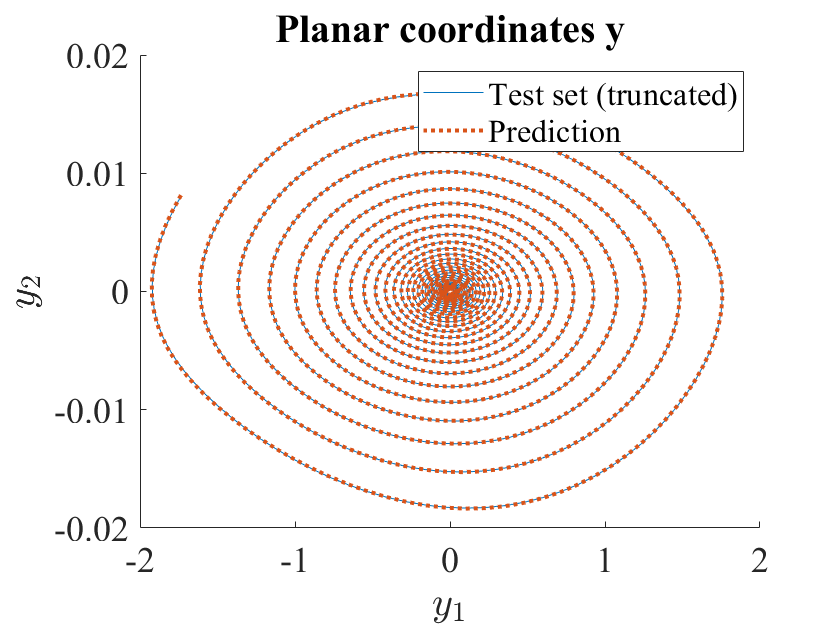

plotReducedCoords(yDataTrunc(indTest(1),:), yRecNormal(indTest(1),:))
legend({'Test set (truncated)', 'Prediction'})

We also plot the measured and predicted tip displacement. The reduced model seems to do well on previously unseen data, provided that it is initalized close to the 2D manifold.

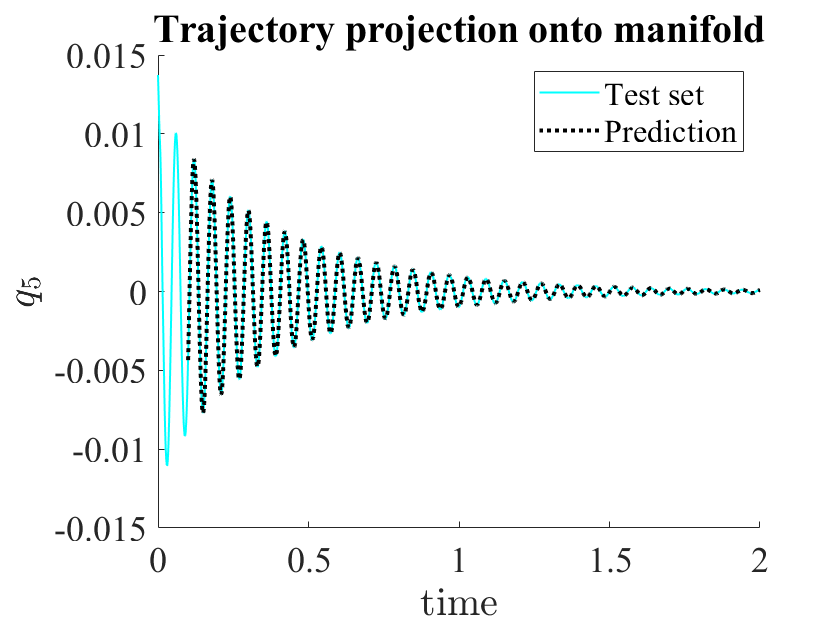

plotReconstructedTrajectory(xData(indTest(1),:), xRecNormal(indTest(1),:), n-1, 'c')
legend({'Test set', 'Prediction'})

Finally we compare the estimated eigenvalues of the continuous evolution function to the ones computed with SSMTool. 

SSM(DS).choose_E(1:SSMDim);

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.215952e-02
modal damping ratio for 2 mode is 1.399821e-01
modal damping ratio for 3 mode is 4.734451e-01
modal damping ratio for 4 mode is 1.374140e+00
modal damping ratio for 5 mode is 1.758199e+00

 The first 10 eigenvalues are given as 
   1.0e+04 *

  -0.0002 + 0.0103i
  -0.0002 - 0.0103i
  -0.0091 + 0.0647i
  -0.0091 - 0.0647i
  -0.1046 + 0.1946i
  -0.1046 - 0.1946i
  -0.2561 + 0.0000i
  -0.2768 + 0.0000i
  -1.4856 + 0.0000i
  -2.6291 + 0.0000i

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 11473
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     1     2
     2     3

These are in resonance with the follwing eigenvalues of the master s

lambda = DS.spectrum.Lambda;
DSEigenvalues = lambda(1:SSMDim)

DSEigenvalues = 	1.0e+02 *

  -0.0229 + 1.0339i
  -0.0229 - 1.0339i


normalFormEigenvalues = computeEigenvaluesMap(NormalFormInfo, dt)

normalFormEigenvalues = 	1.0e+02 *

  -0.0231 + 1.0323i
  -0.0231 - 1.0323i


## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency.

N_info = NormalFormInfo.N;
[damp,freq] = nonres_normalform(N_info.coeff,N_info.exponents);

The data-driven polar normal form dynamics reads:

                         1           r^2    
                      ________    __________

    \dot{r}/r =         0.9961    -0.0023859
    \dot{\theta} =    0.068682     0.0051575

Notation: z = r*exp(1i*\theta) where r is the amplitude and \theta the phase; r^k is the k-th power of r.


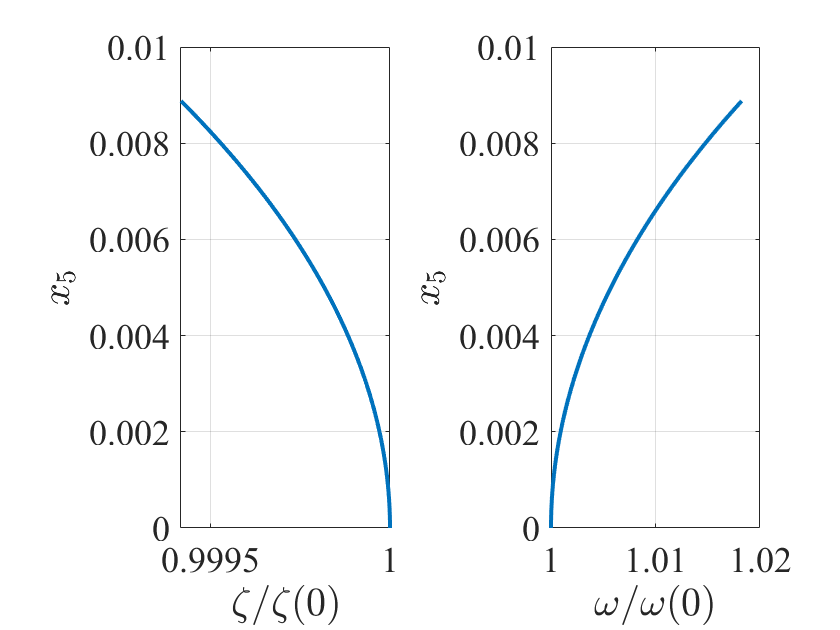

figure
maxRho = abs(zData{indTest(1),2}(1,1));
backbonecurves(damp, freq, SSMFunction, T, n-1, maxRho, dt);